# Coordenadas dos nós

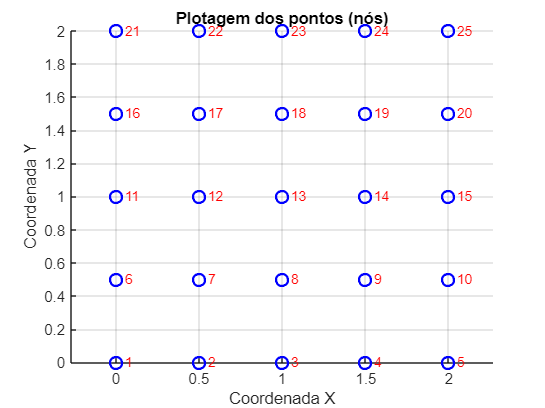

clear all
clc

% Inicializando as coordenadas dos pontos
gcoord = zeros(25, 2);

% Preenchendo as coordenadas X
gcoord(1:5, 1) = 0:0.5:2;
gcoord(6:10, 1) = 0:0.5:2;
gcoord(11:15, 1) = 0:0.5:2;
gcoord(16:20, 1) = 0:0.5:2;
gcoord(21:25, 1) = 0:0.5:2;

% Preenchendo as coordenadas Y
gcoord(1:5, 2) = 0;
gcoord(6:10, 2) = 0.5;
gcoord(11:15, 2) = 1;
gcoord(16:20, 2) = 1.5;
gcoord(21:25, 2) = 2;

% Plotando os pontos
figure;
hold on;
grid on;

for i = 1:size(gcoord, 1)
    % Plotando cada nó
    plot(gcoord(i, 1), gcoord(i, 2), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5);
    % Adicionando o número do nó
    text(gcoord(i, 1) + 0.05, gcoord(i, 2), num2str(i), 'FontSize', 9, 'Color', 'r');
end

% Configurações do gráfico
title('Plotagem dos pontos (nós)');
xlabel('Coordenada X');
ylabel('Coordenada Y');
axis equal;

## Conectividades dos elementos

nodes(1,:)=[1 3 11 2 7 6];
nodes(2,:)=nodes(1,:)+2*ones(1,6);
nodes(3,:)=[3 13 11 8 12 7];
nodes(4,:)=nodes(3,:)+2*ones(1,6);
nodes(5,:)=[11 13 21 12 17 16];
nodes(6,:)=nodes(5,:)+2*ones(1,6);
nodes(7,:)=[13 23 21 18 22 17];
nodes(8,:)=nodes(7,:)+2*ones(1,6);